# Sparse Flux Balance Analysis 

## Author: Ronan Fleming, Hoai Minh Le, Systems Biochemistry Group, University of Luxembourg.

## Reviewer:

## INTRODUCTION

We consider a biochemical network of  m  molecular species and  n  biochemical reactions. The biochemical network is mathematically represented by a stoichiometric matrix $S\in\mathcal{Z}^{m\times n}$. In standard notation, flux balance analysis (FBA) is the linear optimisation problem


$$\begin{array}{ll}
\min\limits _{v} & \rho(v)\equiv c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $$c\in\Re^{n}$$ is a parameter vector that linearly combines one or more reaction fluxes to form what is termed the objective function,  and where a $$b_{i}<0$$, or  $$b_{i}>0$$, represents some fixed output, or input, of the ith molecular species. A typical application of flux balance analysis is to predict an optimal non-equilibrium steady-state flux vector that optimises a linear objective function, such biomass production rate, subject to bounds on certain reaction rates. Herein we use sparse flux balance analysis to predict a minimal number of active reactions [[melendez-hevia_game_1985](#LyXCite-melendez_hevia_game_1985)], consistent with an optimal objective derived from the result of a standard flux balance analysis problem. In this context *sparse flux balance analysis *requires a solution to the following problem


$$\begin{array}{ll}
\min\limits _{v} & \Vert v\Vert_{0}\\
\text{s.t.} & Sv=b\\
 & l\leq v\leq u\\
 & c^{T}v=\rho^{\star}
\end{array}$$


where the last constraint is represents the requirement to satisfy an optimal objective value $\rho^{\star}$  derived from any solution to a flux balance analysis (FBA) problem.

## PROCEDURE

Set the tolerance to distinguish between zero and non-zero flux, based on the numerical tolerance of the currently installed optimisation solver.

feasTol = getCobraSolverParams('LP', 'feasTol');

Load Recon3.0model, unless it is already loaded into the workspace.

clear model
if ~exist('modelOrig','var')
    filename='Recon3.0model';
    directory='~/work/sbgCloud/programReconstruction/projects/recon2models/data/reconXComparisonModels';
    model = loadIdentifiedModel(filename,directory);
    model.csense(1:size(model.S,1),1)='E';
    modelOrig = model;
else
    model=modelOrig;
end

Display the constraints

minInf=-1000;
maxInf=1000;
printConstraints(model, minInf, maxInf);

Select the biomass reaction to optimise

model.biomassBool=strcmp(model.rxns,'biomass_reaction');
model.c(model.biomassBool)=1;

Display the biomass reaction

rxnAbbrList={'biomass_reaction'};
printFlag = 1;
formulas = printRxnFormula(model, rxnAbbrList, printFlag);        

##  Sparse flux balance analysis

We provide two options to run sparse flux balance analysis. A: directly in one step, no quality control, and B: two steps, all approximations, with a heuristic sparsity test**.**

## TIMING

The time to compute a sparse flux balance analysis solution depends on the size of the genome-scale model and the option chosen to run sparse flux balance analysis.  Option A: directly in one step, no quality control, can take anything from <0.1 seconds for a 1,000 reaction model, to 1,000 seconds for a model with 20,000 reactions. Option B: two steps, all approximations, with a sparsity test could take hours for a model with >10,000 reactions because the length of time for the heuristic sparsity test is proportional to the number of active reactions in an approximate sparse solution.

## **A. Sparse flux balance analysis (directly in one step, no quality control)**

This approach computes a sparse flux balance analysis solution, satisfing the FBA objection, with the default approach to approximate the solution to the cardinality minimisation problem underling sparse FBA. This approach does not check the quality of the solution, i.e., whether indeed it is the sparsest flux vector satisfing the optimality criterion $c^{T}v=\rho^{\star}$.

First choose whether to maximize ('max') or minimize ('min') the FBA objective. Here we choose maximise

osenseStr='max';

Choose to minimize the zero norm of the optimal flux vector

minNorm='zero';

Run sparse flux balance analysis

sparseFBAsolution = optimizeCbModel(model, osenseStr, minNorm);

Obtain the vector of reaction rates from the solution structure

v = sparseFBAsolution.v;

Display the sparse flux solution, but only the non-zero fluxes

nonZeroFlag = 1;
printFluxVector(model, v, nonZeroFlag);

Display the number of active reactions

fprintf('%u%s\n',nnz(v),' active reactions in the sparse flux balance analysis solution.');

## ANTICIPATED RESULTS

Typically, a sparse flux balance analysis solution will have a small fraction of the number of the number of reactions active than in a flux balance analysis solution, e.g., Recon3.0model has 10,600 reactions. When maximising biomass production, a typical flux balance analysis solution might have approximately 3,000 active reactions (this is LP solver dependent) whereas for the same problem there are 435 active reactions in the sparse flux balance analysis solution from optimizeCbModel (using the default capped L1 norm approximate step function, see below).

## **B. Sparse flux balance analysis (two steps, all approximations,** **with a sparsity test)**

This approach computes a sparse flux balance analysis solution, satisfing the FBA objection, with the default approach to approximate the solution to the cardinality minimisation problem underling sparse FBA. This approach does not check the quality of the solution, i.e., whether indeed it is the sparsest flux vector satisfing the optimality criterion $c^{T}v=\rho^{\star}$.

## Solve a flux balance analysis problem

Build a linear programming problem structure (LPproblem) that is compatible with the interfacefunction (solveCobraLP) to any installed linear optimisation solver.

[c,S,b,lb,ub,csense] = deal(model.c,model.S,model.b,model.lb,model.ub,model.csense);
[m,n] = size(S);

LPproblem = struct('c',c,'osense',-1,'A',S,'csense',csense,'b',b,'lb',lb,'ub',ub);

Now solve the flux balance analysis problem

LPsolution = solveCobraLP(LPproblem);
if LPsolution.stat == 1
    vFBA = LPsolution.full(1:n);
else
    vFBA = [];
    error('FBA problem error!')
end

Display the number of active reactions

fprintf('%u%s\n',nnz(vFBA),' active reactions in the flux balance analysis solution.');

## Approimations underlying sparse flux balance analysis

Due to its combinatorial nature, minimising the zero norm explicitly is an NP-hard problem. Therefore we approximately solve the problem. The approach is to replace the zero norm with a separable sum of step functions, which are each approximated by anther function. Consider the step function ς(t): R  →  R where ς (t)=1 if t ≠ 0 and     ς (t)=0 otherwise, illustrated in the Figure below:

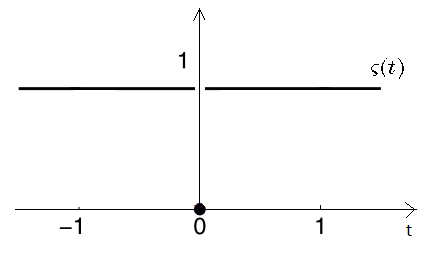

There are then many different approximate step functions that can be minimised. The figure below illustrates the many different approximate step functions that can be chosen to be minimised instead of an explicit step function.

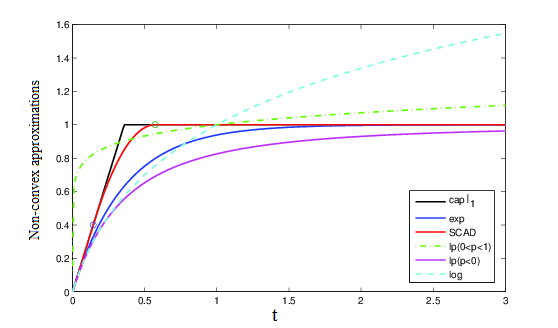

Depending on the application, and the biochemical network, one or other approximation may outperform the rest, therefore a pragmatic strategy is to try each and select the most sparse flux vector. The step set of function approximations available are

 * 'cappedL1' : Capped-L1 norm

 * 'exp'      : Exponential function

 * 'log'      : Logarithmic function

 * 'SCAD'     : SCAD function

 * 'lp-'      : L_p norm with p<0

 * 'lp+'      : L_p norm with 0<p<1

Here we prepare a cell array of strings which indicate the set of step function approximations we wish to compare.

approximations = {'cappedL1','exp','log','SCAD','lp-','lp+'};

## Run the sparse linear optimisation solver

First we must build a problem structure to pass to the sparse solver, by adding an additional constraint requiring that the sparse flux solution also statisfy the optimal objective value from flux balance analysis

constraint.A = [S ; c'];
constraint.b = [b ; c'*vFBA];
constraint.csense = [csense;'E'];
constraint.lb = lb;
constraint.ub = ub;

Now we call the sparse linear step function approximations  

bestResult = n;
bestAprox = '';
for i=1:length(approximations)
    solution = sparseLP(char(approximations(i)),constraint);
    if solution.stat == 1
        nnzSol=nnz(abs(solution.x)>feasTol);
        fprintf('%u%s%s',nnzSol,' active reactions in the sparseFBA solution with ', char(approximations(i)));
        if bestResult > nnzSol
            bestResult=nnzSol;
            bestAprox = char(approximations(i));
            solutionL0 = solution;
        end
    end
end

Select the most sparse flux vector, unless there is a numerical problem.

if ~isequal(bestAprox,'')
    vBest = solutionL0.x;
else
    vBest = [];
    error('Min L0 problem error !!!!')
end

Report the best approximation

display(strcat('Best step function approximation: ',bestAprox));

Report the number of active reactions in the most sparse flux vector

fprintf('%u%s',nnz(abs(vBest)>feasTol),' active reactions in the best sparse flux balance analysis solution.');

Warn if there might be a numerical issue with the solution

feasError=norm(constraint.A * solutionL0.x - constraint.b,2);
if feasError>feasTol
    fprintf('%g\t%s\n',feasError, ' feasibily error.')
    warning('Numerical issue with the sparseLP solution')
end

## Heuristically check if the selected set of reactions is minimal

Each step function approximation minimises a different problem than minimising the zero norm explicitly. Therefore it is wise to test, at least heuristically, if the most sparse approximate solution to minimising the zero norm is at least locally optimal, in the sense that the set of preicted reactions cannot be reduced by omitting, one by one, an active reaction. If it is locally optimal in this sense, one can be more confident that the  most sparse approximate solution is the most sparse solution, but still there is no global guaruntee, as it is a combinatorial issue.

Identify the set of predicted active reactions

activeRxnBool = abs(vBest)>feasTol;
nActiveRnxs = nnz(activeRxnBool);
activeRxns = false(n,1);
activeRxns(activeRxnBool) = true;
minimalActiveRxns=activeRxns;


Close all predicted non-active reactions by setting their lb = ub = 0

lbSub = model.lb;
ubSub = model.ub;
lbSub(~activeRxns) = 0;
lbSub(~activeRxns) = 0;

Generate an LP problem  to be reduced

% Check if one still can achieve the same objective
LPproblem = struct('c',-c,'osense',-1,'A',S,'csense',csense,'b',b,'lb',lbSub,'ub',ubSub);

For each active reaction in the most sparse approximate flux vector, one by one, set the reaction bounds to zero, then test if the optimal flux balance analysis objective value is still attained. If it is, then that reaction is not part of the minimal set. If it is not, then it is probably part of the minimal set.

for i=1:n
    if activeRxnBool(i)
        LPproblem.lb = model.lb;
        LPproblem.ub = model.ub;
        %close bounds on this reaction
        LPproblem.lb(i) = 0;% Close the reaction
        LPproblem.ub(i) = 0;% Close the reaction
        %solve the LP problem
        LPsolution = solveCobraLP(LPproblem);
        %check if the optimal FBA objective is attained
        if LPsolution.stat == 1 && abs(LPsolution.obj + c'*vFBA)<1e-8
            minimalActiveRxns(i) = 0;
            vBestTested = LPsolution.full(1:n);
        else
            %relax those bounds if reaction appears to be part of the minimal set
            LPproblem.lb(i) = model.lb(i);
            LPproblem.ub(i) = model.ub(i);
        end
    end
end

Report the number of active reactions in the approximately most sparse flux vector, or the reduced approximately most sparse flux vector, if it is more sparse.

if nnz(minimalActiveRxns)<nnz(activeRxns)
    fprintf('%u%s',nnz(abs(vBestTested)>feasTol),' active reactions in the best sparseFBA solution (tested).');
    nonZeroFlag = 1;
    printFluxVector(model, vBestTested, nonZeroFlag);
else
    fprintf('%u%s',nnz(abs(vBest)>feasTol),' active reactions in the best sparseFBA solution (tested).');
end

## REFERENCES

[fleming_cardinality_nodate] Fleming, R.M.T., et al., Cardinality optimisation in constraint-based modelling: illustration with Recon 3D (submitted), 2017.

[[sparsePaper](#LyXCite-sparsePaper)] Le Thi, H.A., Pham Dinh, T., Le, H.M., and Vo, X.T. (2015). DC approximation approaches for sparse optimization. European Journal of Operational Research 244, 26–46.